Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Matching the phase advances (Section 3.6.1)

Volker Ziemann, 211107, CC-BY-SA-4.0

**Important: **requires the functions for the 4D calculations, available in the `chap3/4D` subdirectory from the zip file with all MATLAB scripts. Needed for `calcmat()` and `plot_betas(). `

In this example we will start from  the FODO cell that we used before and will find focal lengths of the two quadrupoles that will cause the horizontal pahse advace of one cell to be $60^o$ and the vertical phase advance to be $90^o$. Colloquially we sat that we set the tune per cell to 1/6 and 1/4.  

% match the tunes in a FODO cell
clear all; close all
addpath ./4D       % use the 4D software
global beamline
F=2.1;
fodo=[ 1,  5,  0.2,  0;  
	     2,  1,  0.0, -F;    % QD
	     1, 10,  0.2,  0;    
	     2,  1,  0.0,  F;    % QF
       1,  5,  0.2,  0]   

fodo =     1.0000    5.0000    0.2000         0
    2.0000    1.0000         0   -2.1000
    1.0000   10.0000    0.2000         0
    2.0000    1.0000         0    2.1000
    1.0000    5.0000    0.2000         0


beamline=fodo;

Now we are ready to calculate the transfer matrices Racc, the periodic beam matrix sigma0 that we use as initial value for plotting the beta functions.

[Racc,spos]=calcmat(beamline); Rend=Racc(:,:,end)

Rend =     1.4989    3.5465         0         0
   -0.4535   -0.4059         0         0
         0         0   -0.4059    3.5465
         0         0   -0.4535    1.4989


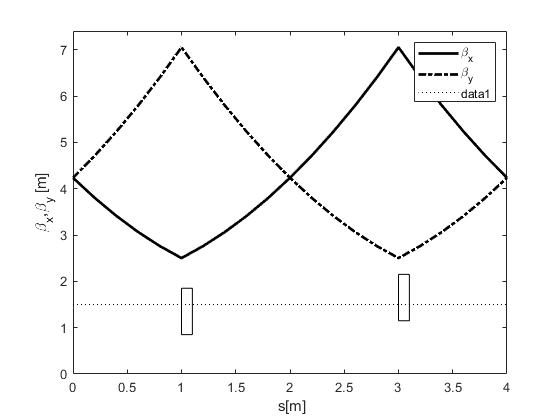

sigma0=periodic_beammatrix(Rend,1,1);
plot_betas(beamline,sigma0); 
drawmag(beamline,1,1)

Q=tunes(Rend)

Q =     0.1580    0.1580


Here we use service functions to calculate the periodic beam matrix (with emittances set to 1), plotting the beta functions, drawing the magnet lattice and calculating the tunes. Note that we find the tunes to be 0.158 in both transverse planes. But we want them to be 1/6 and 1/4 instead, so we define a chisq function (see below) that varies the focal lengths of the quads and returns the squared difference between the desired and the actually acheived tunes. We then pass this function` chisq_tunes()` to` fminsearch() `to find the new focal lengths.

f0=[2,-2];  % starting guess
[f,fval]=fminsearch(@chisq_tunes,f0)

f =     1.8081   -1.4748


fval = 4.7549e-11

Once we have the quad settings, we update all transfer matrices, calculate the periodic beam matrix, open a new figure and plot the beta functions and a the postions of the magnets with `drawmag()`. Finally we calculate the tunes and verify that they are indeed 0.1666 and 0.25 and then write the beamline description with the new quad settings to a file called `fodo6090.bl.`

[Racc,spos]=calcmat(beamline); Rend=Racc(:,:,end)

Rend =    -0.7312    3.6250         0         0
   -0.6250    1.7311         0         0
         0         0    1.2311    2.8750
         0         0   -0.8750   -1.2311


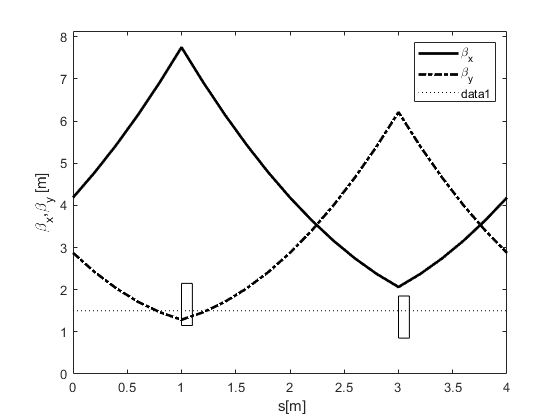

sigma0=periodic_beammatrix(Rend,1,1);
figure
plot_betas(beamline,sigma0); 
drawmag(beamline,1,1)

Q=tunes(Rend)

Q =     0.1667    0.2500


dlmwrite('fodo6090.bl',beamline,'\t')

If we want to work with these cells further, we simply load `fodo6090.bl `with` dlmread()` and use it as the starting point for further explorations.

## chisq_tunes()

This following function` chisq_tunes() `receives the focal lenths as input, and returns the squared difference between the desired and the actually calculated tunes. Inside the function first the focal lenths in the fourth column of entry 2 and 4 of the beamline are updated, then the tranbsfer matrices are updated and the tunes are extracted, before the difference to the desired values is determined.

function chisq=chisq_tunes(x)
global beamline      % need info about the beamline
beamline(2,4)=x(1); 
beamline(4,4)=x(2);
[Racc,spos]=calcmat(beamline);
Rturn=Racc(:,:,end); 
[Qx,alpha0x,beta0x,gamma0x]=R2beta(Rturn(1:2,1:2));
[Qy,alpha0y,beta0y,gamma0y]=R2beta(Rturn(3:4,3:4));
chisq=(Qx-1/6)^2+(Qy-0.25)^2; % desired tunes
end